%% DFMT communication demo
clear; clc; close all;

fs = 44100;          % Sampling frequency
Tsym = 0.1;          % Symbol duration (s)
tSym = 0:1/fs:Tsym-1/fs;

% --- Define DFMT tone table ---
toneTable = [1000 1500;  % 00
              1000 2000;  % 01
              1500 2500;  % 10
              2000 2500]; % 11
nTones = unique(toneTable(:))';

msg = 'HI';  % Text message

%% --- Sender side ---
% Convert to bits
binStr = reshape(dec2bin(msg,8).'-'0',1,[]);

% Pad to multiple of 2 bits
if mod(length(binStr),2)~=0
    binStr = [binStr 0];
end

% Compute parity checksum (simple even parity)
checksum = mod(sum(binStr),2);
txBits = [binStr checksum 0];  % add a dummy 0 for pair alignment

% Group into 2-bit symbols
txSym = reshape(txBits,2,[])';
nSym = size(txSym,1);

% Generate DFMT signal
signal = [];
for i = 1:nSym
    idx = bin2dec(sprintf('%d', txSym(i,:))) + 1;
    freqs = toneTable(idx,:);
    s = sin(2*pi*freqs(1)*tSym) + sin(2*pi*freqs(2)*tSym);
    signal = [signal s];
end

% Normalize
signal = signal / max(abs(signal));

% Simulate channel noise
rxSignal = signal + 0.02*randn(size(signal));

%% --- Receiver side ---
rxBits = [];
for i = 1:nSym
    seg = rxSignal( (1:length(tSym)) + (i-1)*length(tSym) );

    % Compute magnitude at each candidate frequency
    for f = nTones
        ref = sin(2*pi*f*tSym);
        power(f==nTones) = sum(seg.*ref).^2;
    end

    % Pick top two peaks
    [~,idx] = maxk(power,2);
    freqsDetected = sort(nTones(idx));

    % Find matching row in table
    [~,row] = ismember(freqsDetected, toneTable, 'rows');
    nBits = 2;
    bits = bitget(row-1, nBits:-1:1);
    rxBits = [rxBits bits];
end

% Remove dummy and checksum
rxBits = rxBits(1:end-2);
rxChecksum = mod(sum(rxBits),2);

if rxChecksum ~= checksum
    disp('Checksum failed!');
else
    disp('Checksum OK');
end

Checksum OK



% Convert bits to text
rxChars = char(bin2dec(reshape(char(rxBits+'0'),8,[]).')).';
fprintf('Received message: %s\n',rxChars);

Received message: HI


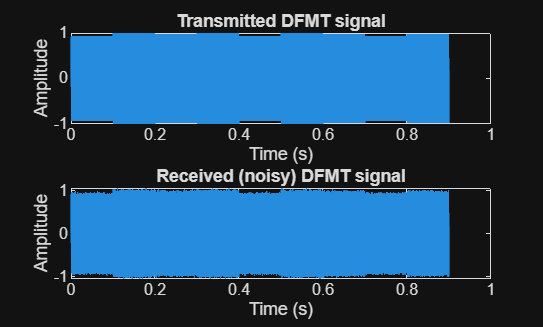


%% --- Visualization ---
t = (0:length(signal)-1)/fs;
figure;
subplot(2,1,1)
plot(t, signal)
title('Transmitted DFMT signal')
xlabel('Time (s)'), ylabel('Amplitude')
subplot(2,1,2)
plot(t, rxSignal)
title('Received (noisy) DFMT signal')
xlabel('Time (s)'), ylabel('Amplitude')